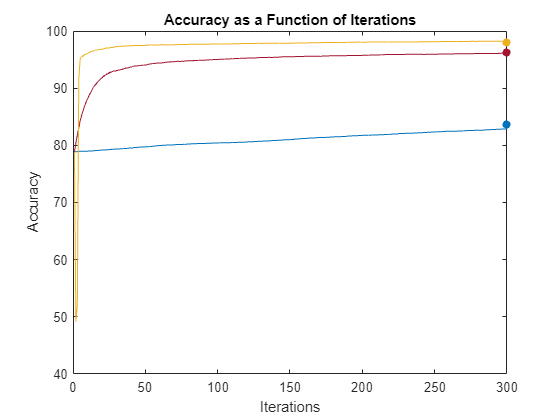

% Gradient descent for the MNIST data set
clear;
%load("C:\Users\phaj2\OneDrive - Loughborough University\computational_portfolio\Semester2\matlab\mnist.mat");
load("C:\Users\Adam\OneDrive - Loughborough University\computational_portfolio\Semester2\matlab\mnist.mat");
data = reshape(XTrain, 28*28, [])';
testData = reshape(XTest, 28*28, [])';

class1 = 5;
class2 = 6;

[twoClassData, twoClassLabels] = extractClasses(data, YTrain, class1, class2);
[twoClassTestData, twoClassTestLabels] = extractClasses(testData, YTest, class1, class2);

solution = zeros(784, 1);
offset = 0;

iterations = 300;
allAccuracyResults = zeros(iterations, 3);
testAccuracyResults = zeros(1, 3);
allCostFunctionResults = zeros(iterations, 3);
testCostFunctionResults = zeros(1, 3);
colIndex = 1;
lRates = [0.0001, 0.01, 1];

for learningRate = lRates
    [solution, offset, accuracyResults, costFunctionResults] = gradientDescent(twoClassData, twoClassLabels, learningRate, iterations);
    allAccuracyResults(:, colIndex) = accuracyResults;
    allCostFunctionResults(:, colIndex) = costFunctionResults;
    [~, ~, ~, sigmoidPredictions] = gradientDescentStep(twoClassTestData, twoClassTestLabels, learningRate, solution, offset);
    testLabelPredictions = guessLabels(twoClassTestData, solution, offset);
    testAccuracy = getAccuracy(testLabelPredictions, twoClassTestLabels);
    testAccuracyResults(1, colIndex) = testAccuracy;
    testCostFunctionResults(1, colIndex) = crossEntropyLoss(twoClassTestLabels, sigmoidPredictions);
    colIndex = colIndex + 1;
end
colours = [0 0.4470 0.7410; 0.6350 0.0780 0.1840; 0.9290 0.6940 0.1250];
ax = gca; 
ax.ColorOrder = colours;

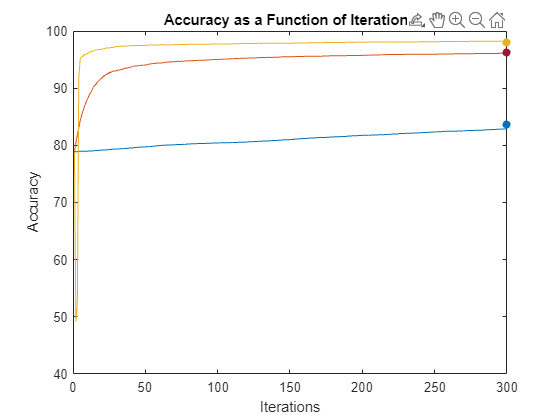


plot(1:iterations, allAccuracyResults)
xlabel("Iterations")
ylabel("Accuracy")
title("Accuracy as a Function of Iterations")
hold on;
colours = [0 0.4470 0.7410; 0.6350 0.0780 0.1840; 0.9290 0.6940 0.1250];
scatter(iterations, testAccuracyResults, [], colours, "filled");
hold off;

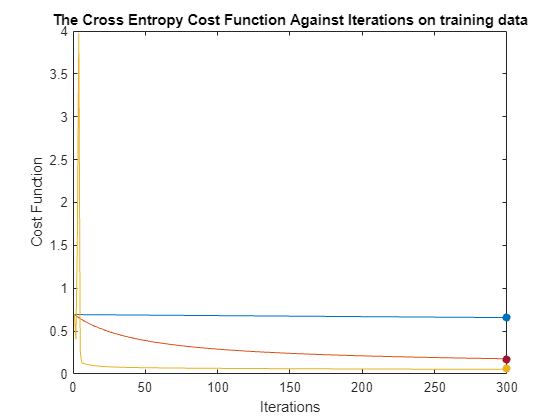


plot(1:iterations, allCostFunctionResults)
xlabel("Iterations")
ylabel("Cost Function")
title("The Cross Entropy Cost Function Against Iterations on training data")
hold on;
scatter(iterations, testCostFunctionResults, [], colours, "filled")
hold off;

% Use to plot cost/acc against iterations
% plot(1:iterations, costFunctionResults)
% xlabel("Iterations")
% ylabel("Cost Function")
% title("Accuracy against Iterations with Learning Rate = 1")